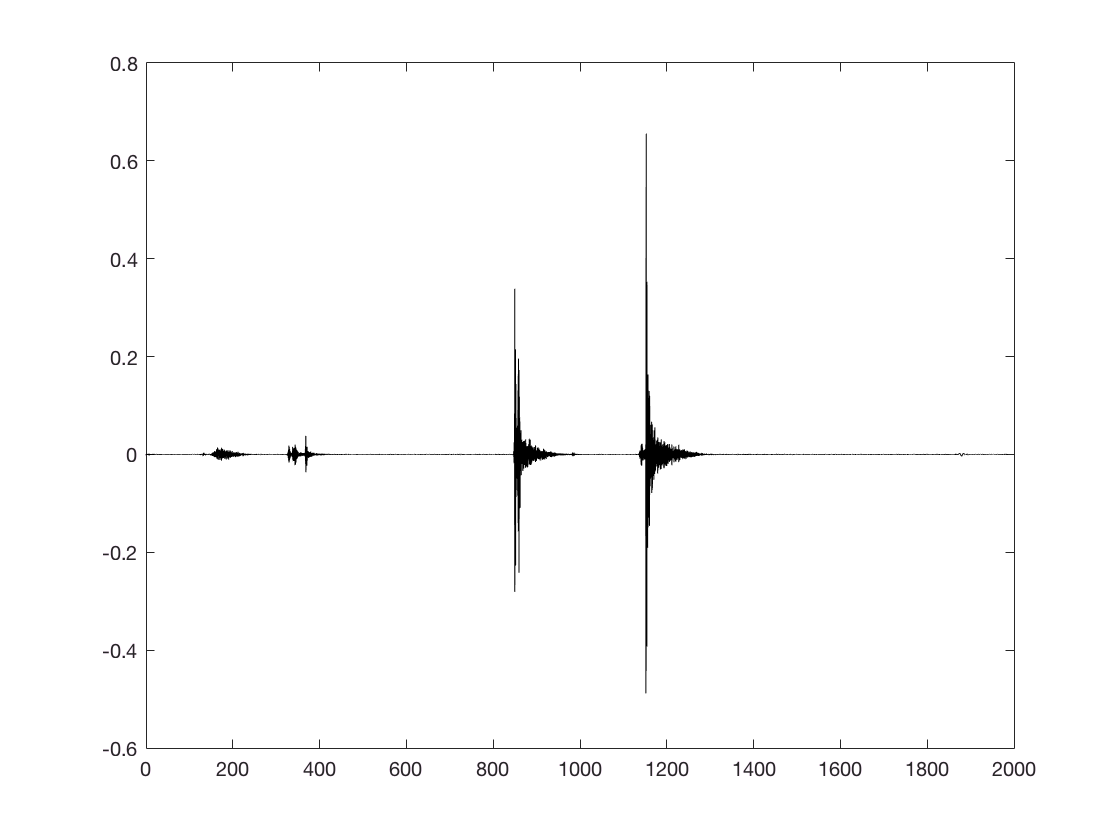

[x,fs] = audioread('p-a-xicun.wav');
tmp = size(x)/fs;
s1 = x(:,1);

peakss1=findpeaks(s1);

timeArray = (0:size(x)-1)/fs;
timeArray = timeArray*1000;

plot(timeArray,s1,'k');

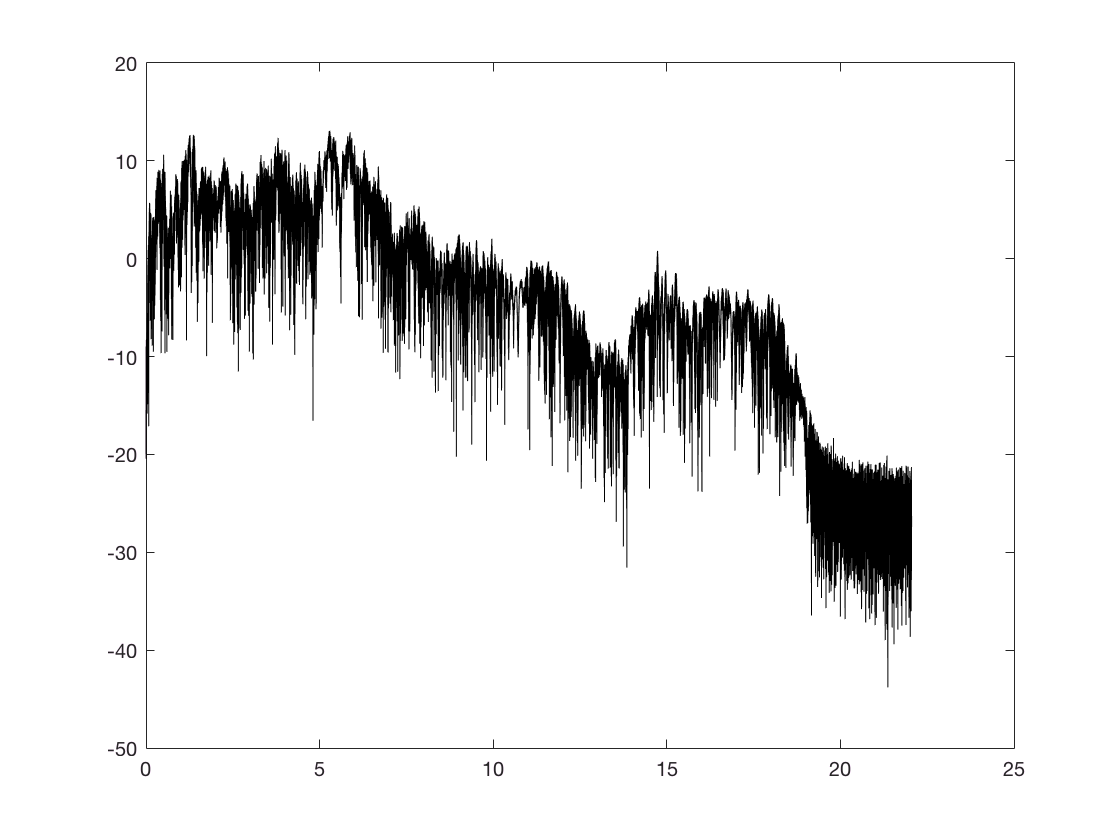


lenS1 = length(s1);
ffTrans = fft(s1);

nUniquePts = ceil((lenS1+1)/2);
ffTrans = ffTrans(1:nUniquePts);

ffTrans = abs(ffTrans);

freqArray = (0:nUniquePts-1)*(fs/lenS1);
plot(freqArray/1000, 10*log10(ffTrans),'k')


[y,fsy ]= audioread('password-xicun.wav')

y =    1.0e-03 *

   -0.0802   -0.0802
   -0.0446   -0.0446
   -0.0154   -0.0154
   -0.0075   -0.0076
    0.0141    0.0141
    0.0720    0.0720
    0.1178    0.1179
    0.1469    0.1469
    0.1209    0.1208
    0.1116    0.1116


fsy = 44100

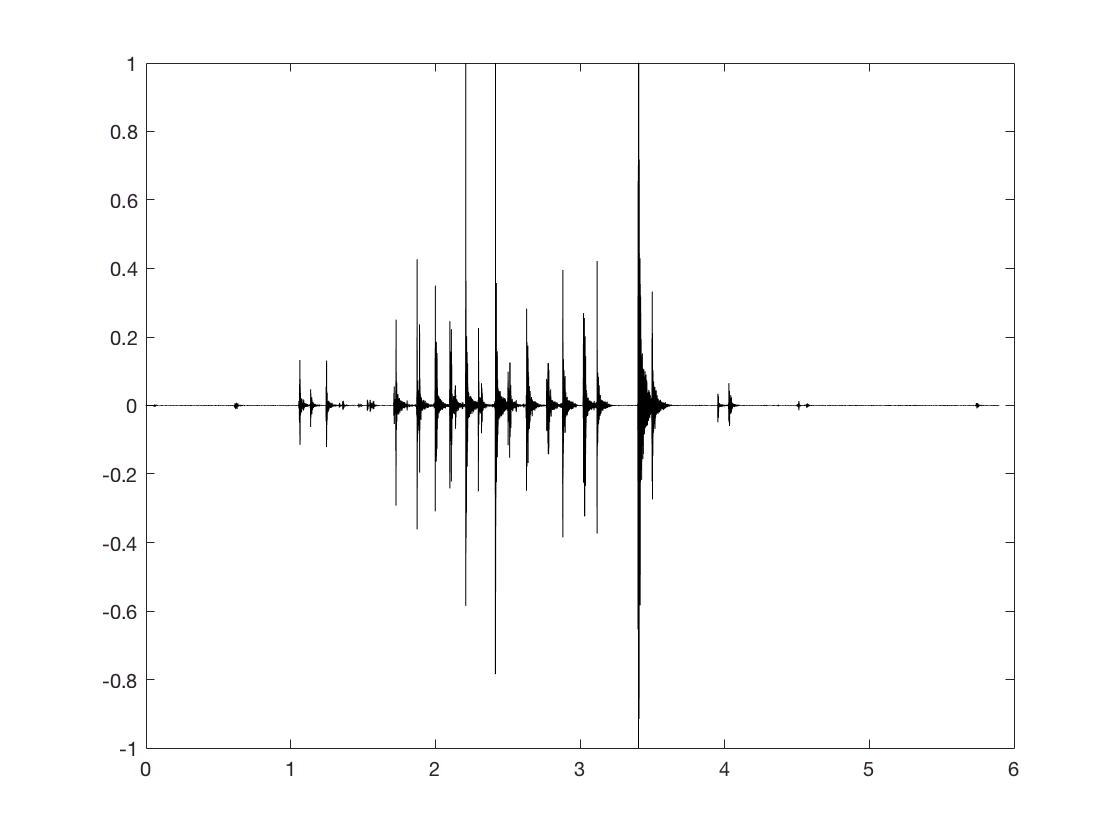

yLeft = y(:,1);
ty = (0:size(yLeft)-1)/fsy;
plot (ty,yLeft,'k');



yrmsenvLeft = sqrt(conv(yLeft.^2,ones(200,1)/200,'same'))

yrmsenvLeft =    1.0e-04 *

    0.9507
    0.9516
    0.9516
    0.9520
    0.9522
    0.9523
    0.9524
    0.9524
    0.9525
    0.9526


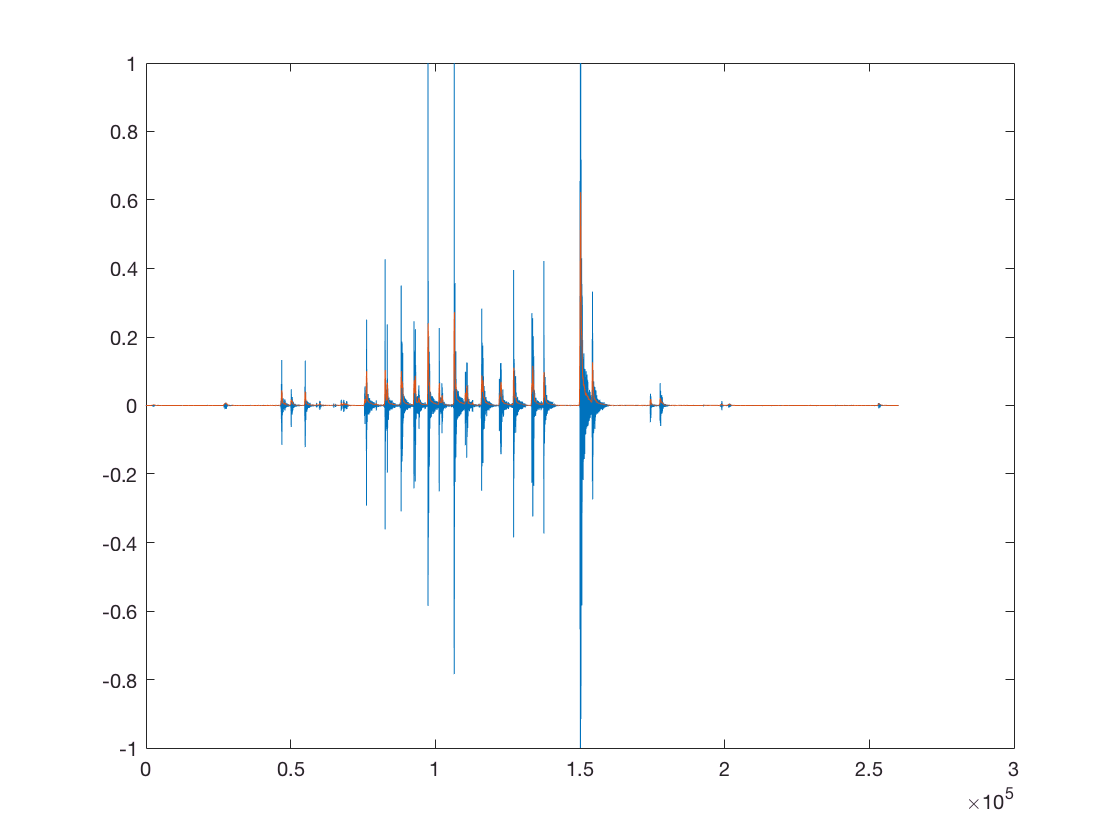

plot([yLeft yrmsenvLeft])